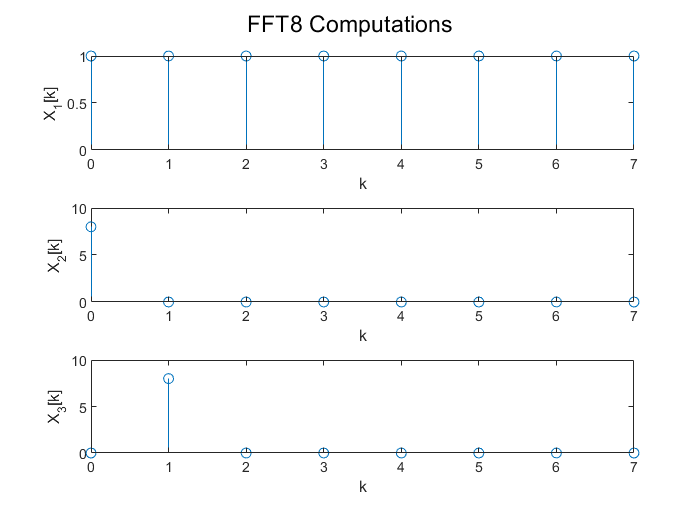

clear;close all;clc;

n=0:1:7;
j=sqrt(-1);

x1=(n==0);
x2=ones(1,8);
x3=exp(j*2*pi*n/8);

figure(1);
sgtitle('FFT8 Computations');
subplot(3,1,1);
X1=FFT8(x1);stem(n,abs(X1));xlabel('k'),ylabel('X_{1}[k]');
subplot(3,1,2);
X2=FFT8(x2);stem(n,abs(X2));xlabel('k'),ylabel('X_{2}[k]');
subplot(3,1,3);
X3=FFT8(x3);stem(n,abs(X3));xlabel('k'),ylabel('X_{3}[k]');

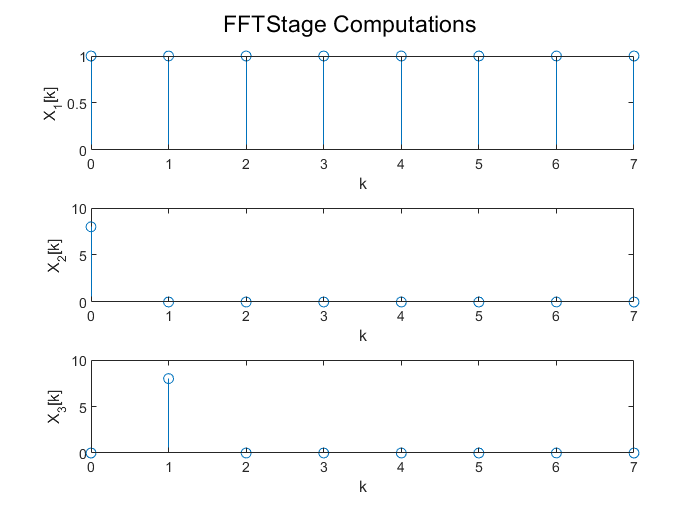


figure(2);
sgtitle('FFTStage Computations');
subplot(3,1,1);
X1_s=fft_stage(x1);stem(n,abs(X1_s));xlabel('k'),ylabel('X_{1}[k]');
subplot(3,1,2);
X2_s=fft_stage(x2);stem(n,abs(X2_s));xlabel('k'),ylabel('X_{2}[k]');
subplot(3,1,3);
X3_s=fft_stage(x3);stem(n,abs(X3_s));xlabel('k'),ylabel('X_{3}[k]');